**Initialize:**

n = 1201;                   % Number of locations to evaluate bridge failure
L = 1200;                   % Length of bridge
x = linspace(0, L, n);      % Define x coordinate
P_each = [-66.7 -66.7 -66.7 -66.7 -90 -90]; % Set train load as 6 point loads applied via the wheels
self = 0.00613; % Self Weight
x0 = 172; % First Point Position


**Load Case 2:**

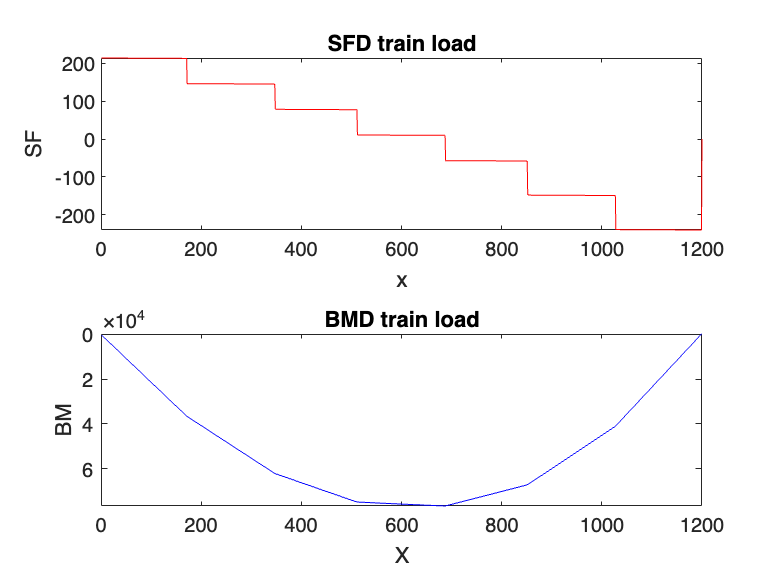

SFD_TL = zeros(1,n);
total_loads = zeros(1, n);
    x_load = [x0,x0+176,x0+340,x0+516,x0+680,x0+856];
    totalB = 0;
    total_load = 0;

    % Support Reactions
    for i = 1:6
        totalB = totalB + (x_load(1,i)*P_each(1,i));
        total_load = total_load + P_each(1,i);
    end
    total_load = total_load - self*L;
    Sup_B = -(totalB - (self*L*L)/2)/L;
    Sup_A = -total_load - Sup_B;
    SFD_TL(1,1) = Sup_A;
    SFD_TL(1,L) = Sup_B;
 

for i = 1:6
    SFD_TL(1,x_load(1,i)) = SFD_TL(1,x_load(1,i)-1) + P_each(1,i);
end

for n = 2:L-1
    SFD_TL(1,n) = SFD_TL(1,n) + SFD_TL(1,n-1)-self;
end

SFD_TL(1,L) = SFD_TL(1,L-1) + Sup_B;
subplot(2,1,1)
plot(SFD_TL,'red') % plot the SF_matrix against x
xlabel('x')
ylabel('SF')
title('SFD train load')

subplot(2,1,2)
plot(BMD_TL,'blue') % plot the BM_matrix against x
xlabel('X')
ylabel('BM')
title('BMD train load')
set(gca, 'YDir', 'reverse')

**Cross-Sections:**

%% 2. Define Cross-Section Inputs & Calculate Cross-Section Properties
% Design0 Cross Section Inputs
xc = [0 400 800 L]; % Location, x, of cross-section change
tfb = [100 100 100 100]; % Top Flange Width
tft = [1.27 1.27 1.27 1.27]; % Top Flange Thickness
wh = [72.46 72.46 72.46 72.46]; % Web Height
wt = [1.27 1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs)
ws = [80 80 80 80]; % Web Spacing
bfb = [80 80 80 80]; % Bottom Flange Width
bft = [1.27 1.27 1.27 1.27]; % Bottom Flange Thickness
gtb = [10 10 10 10]; % Glue Tab Width
gtt = [1.27 1.27 1.27 1.27]; % Glue Tab Thickness

% Interpolate values across every mm of bridge
tfb = interp1(xc, tfb, x);
tft = interp1(xc, tft, x);
wh = interp1(xc, wh, x);
wt = interp1(xc, wt, x);
ws = interp1(xc, ws, x);
bfb = interp1(xc, bfb, x);
bft = interp1(xc, bft, x);
gtb = interp1(xc, gtb, x);
gtt = interp1(xc, gtt, x);

% Calculate cross-section properties
[ybot, ytop, I, Qcent, Qglue] = SectionProperties(x, n, tfb, tft, wh, wt, bfb, bft, gtb, gtt)

ybot =    41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016   41.7016


ytop =    33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984   33.2984


I = 1.0e+05 *

    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569    4.1569


Qcent = 1.0e+03 *

    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484    6.2484


Qglue = 1.0e+03 *

    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483    4.1483


**Material Properties**

%% 3. Define Material Properties
SigT = 30;  % Tensile strength
SigC = 6;   % Compressive strength
E = 4000;   % Young's Modulus
TauU = 4;   % Shear strength, matboard
TauG = 2;   % Shear strength, glue
mu = 0.2;   % Poisson's ratio

**Stress:**

**Functions:**

function [ ybot, ytop, I, Qcent, Qglue ] = SectionProperties ( x, n, ...
    tfb, tft, wh, wt, bfb, bft, gtb, gtt )
% Calculates important sectional properties for left half .
% Including but not limited to ybar, I, Q, etc.
% Input: Geometric Inputs. Format will depend on user
% Output: Sectional Properties at every value of x.
% Each property is a 1-D array of length n

ovheight = tft + wh + bft; % Total height along beam

% Initialize A
tfa = zeros(1, n);
bfa = zeros(1, n);
wa = zeros(1, n);
gta = zeros(1, n);

% Initialize I_0
tfI = zeros(1, n);
bfI = zeros(1, n);
wI = zeros(1, n);
gtI = zeros(1, n);

tfIsum = zeros(1, n);
bfIsum = zeros(1, n);
wIsum = zeros(1, n);
gtIsum = zeros(1, n);

% Initialize ybar, I
ybot = zeros(1, n);
ytop = zeros(1, n);
I = zeros(1, n);

% Initialize Q sum value(s), Qcent, Qglue
wQ = zeros(1, n);
Qcent = zeros(1, n);
Qglue = zeros(1, n);

for i = 1:length(x)
    % Areas, A
    tfa(i) = tfb(i) * tft(i);
    % Assumes all values have been interpolated already
    bfa(i) = bfb(i) * bft(i); 
    % If thickness remains constant, use # instead of vector
    wa(i) = 2 * wh(i) * wt(i); % Assumes 2 webs
    gta(i) = 2 * gtb(i) * gtt(i); % Assumes 2 glue tabs
    
    % Local centroids, y
    tfy = ovheight - (tft ./ 2);
    bfy = bft ./ 2;
    wy = (wh ./ 2) + bft;
    gty = ovheight(i) - tft(i) - (gtt ./ 2);

    % Global centroid, ybar
    ybot(i) = (tfa(i) * tfy(i) + bfa(i) * bfy(i) + wa(i) * wy(i) + ...
        gta(i) * gty(i)) / (tfa(i) + bfa(i) + wa(i) + gta(i));
    ytop(i) = abs(ybot(i) - ovheight(i));
    
    % I naught, I_0
    tfI(i) = (tfb(i) * (tft(i)^3)) / 12;
    bfI(i) = (bfb(i) * (bft(i)^3)) / 12;
    wI(i) = 2 * (wt(i) * (wh(i)^3)) / 12;
    gtI(i) = 2 * (gtb(i) * (gtt(i)^3)) / 12;

    tfIsum(i) = tfI(i) + tfa(i) * (abs(ybot(i) - tfy(i)))^2;
    bfIsum(i) = bfI(i) + bfa(i) * (abs(ybot(i) - bfy(i)))^2;
    wIsum(i) = wI(i) + wa(i) * (abs(ybot(i) - wy(i)))^2;
    gtIsum(i) = gtI(i) + gta(i) * (abs(ybot(i) - gty(i)))^2;

    % Second moment of area, I
    I(i) = tfIsum(i) + bfIsum(i) + wIsum(i) + gtIsum(i);

    % First moment of area, Q (Qcent & Qglue)
    wQ(i) = (2 * wt(i) * (ybot(i)-bft(i))) * ((ybot(i)-bft(i)) / 2);
    Qcent(i) = bfa(i) * (ybot(i)-(bft(i)/2)) + wQ(i);
    Qglue(i) = tfa(i) * (tfy(i) - ybot(i));
end
end